clear
% ECSE 563 assigmenet 3
% Ali Seifeldin
% https://github.com/Bakalala/MGCILL-ECSE-563

% Question 1.a

% R = delta f / delta Pe

% 5% decrease in f, 100% increase in active P

f = 60 %Hz

f = 60

Pe1 = 500 % MW

Pe1 = 500

Pe2 = 250 % MW

Pe2 = 250


PeSystem = 2000 % MW

PeSystem = 2000



R1 = f * .05 / Pe1 % Hz/Mw

R1 = 0.0060

R2 = f * .05 / Pe2 % Hz/Mw

R2 = 0.0120


R1Hzpu = R1 * PeSystem % Hz/p.u.

R1Hzpu = 12

R2Hzpu = R2 * PeSystem % Hz/p.u.

R2Hzpu = 24



% To get p.u / p.u, 2000 MW p.u., 60 Hz p.u.

R1pu = R1 * PeSystem / f % p.u./p.u.

R1pu = 0.2000

R2pu = R2 * PeSystem / f % p.u./p.u.

R2pu = 0.4000

% Question 1.b

% J = (2 Wk0) / w0^2 J/
% M = w0 J / = (2 Wk0) / w0

w0 = 2 * pi * f % rad / s

w0 = 376.9911

Wk0 = 21 * 10^9 % GJ

Wk0 = 2.1000e+10

Wk0_MWs = Wk0 / 1e6; % MW·s 


M = 2 * Wk0_MWs /w0 % MW s^2 /rad.

M = 111.4085

Mpu = M / PeSystem % p.u. s^2 / rad

Mpu = 0.0557

% Question 1.c

Tch1 = 3 %s

Tch1 = 3

Tch2 = 8 %s

Tch2 = 8


Tg1 = 0.25

Tg1 = 0.2500

Tg2 = 0.50

Tg2 = 0.5000


R1 = 0.0060 * 2 * pi % rad / s MW 

R1 = 0.0377

R2 = 0.0120 * 2 * pi % rad / s MW 

R2 = 0.0754


M = 1.1141e+08 / 10^6 % convert to MW s^2 / rad

M = 111.4100

D = 20 / ( 2 * pi) % MW s / rad

D = 3.1831


% we do the math in MW rads/s

mdl = 'ass3q1c';
load_system(mdl);
set_param(mdl, 'StopTime', '30');

%% Run simulation
out = sim(mdl);

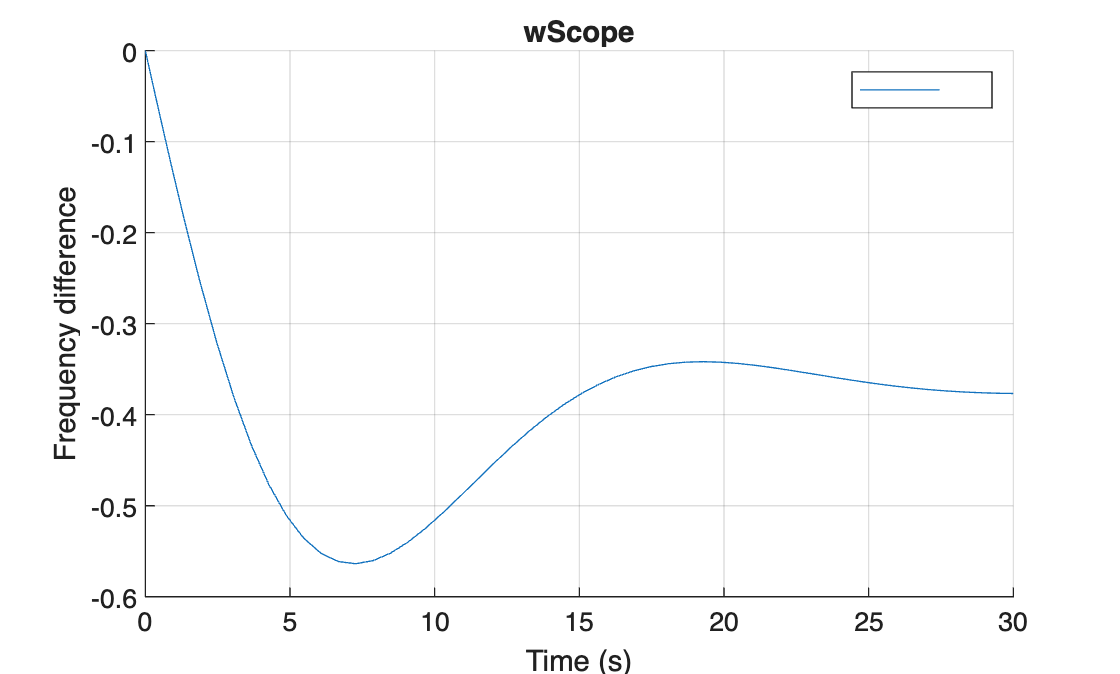

% Question 1.c

scopeNames = {'wScope'};

for i = 1:numel(scopeNames)
    name = scopeNames{i};

    % Try to get dataset directly from 'out'
    try
        ds = out.get(name);
    catch
        % Otherwise get it from logsout
        ds = out.logsout.get(name);
    end

    % Plot all signals in this dataset
    figure('Name', name, 'NumberTitle', 'off');
    hold on; grid on;
    for j = 1:ds.numElements
        sig = ds.get(j);
        plot(sig.Values.Time, sig.Values.Data, 'DisplayName', sig.Name);
    end
    xlabel('Time (s)');
    ylabel('Frequency difference');
    title(name);
    legend('show');
end



% we can see that the frequency drops and reaches a nadir of -.55Hz and
% stablises around -.37 Hz
% --> 60 - 0.37Hz so 59.63Hz is the steady state freq
% Simulation is run using rad / s MW

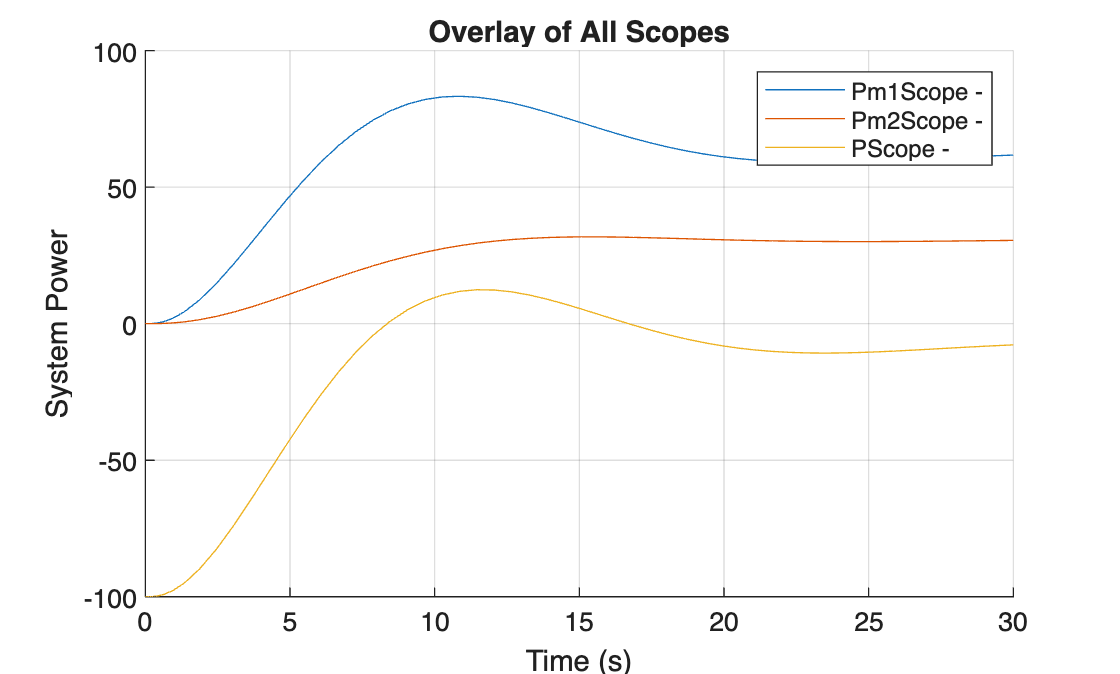

% Question 1.d

scopeNames = {'Pm1Scope','Pm2Scope','PScope'};

figure; hold on; grid on;

for i = 1:numel(scopeNames)
    name = scopeNames{i};

    % Try to get dataset directly from 'out'
    try
        ds = out.get(name);
    catch
        % Otherwise get it from logsout
        ds = out.logsout.get(name);
    end

    % Plot each signal in this scope
    for j = 1:ds.numElements
        sig = ds.get(j);
        plot(sig.Values.Time, sig.Values.Data, 'DisplayName', [name ' - ' sig.Name]);
    end
end

xlabel('Time (s)');
ylabel('System Power');
title('Overlay of All Scopes');
legend('show', 'Interpreter', 'none');


% Pm1 and Pm2 start to ramp up, Pm1 ramps up much faster and does more 'effort' and then eventually
% stablize to a 2/3 and 1/3 split. between both
% we can see on Pscope that with an initial -100 MW, it quikcly shoots up
% to ~+20 MW and stablizes close to the -10 MW.
% the results are consistent with the droop control 

% Question 1.e

Tch1 = 3 %s

Tch1 = 3

Tch2 = 8 %s

Tch2 = 8


Tg1 = 0.25

Tg1 = 0.2500

Tg2 = 0.50

Tg2 = 0.5000


R1 = 0.0060 * 2 * pi % rad / s MW 

R1 = 0.0377

R2 = 0.0120 * 2 * pi % rad / s MW 

R2 = 0.0754


M = 1.1141e+08 / 10^6 % convert to MW s^2 / rad

M = 111.4100

D = 20 / ( 2 * pi) % MW s / rad

D = 3.1831

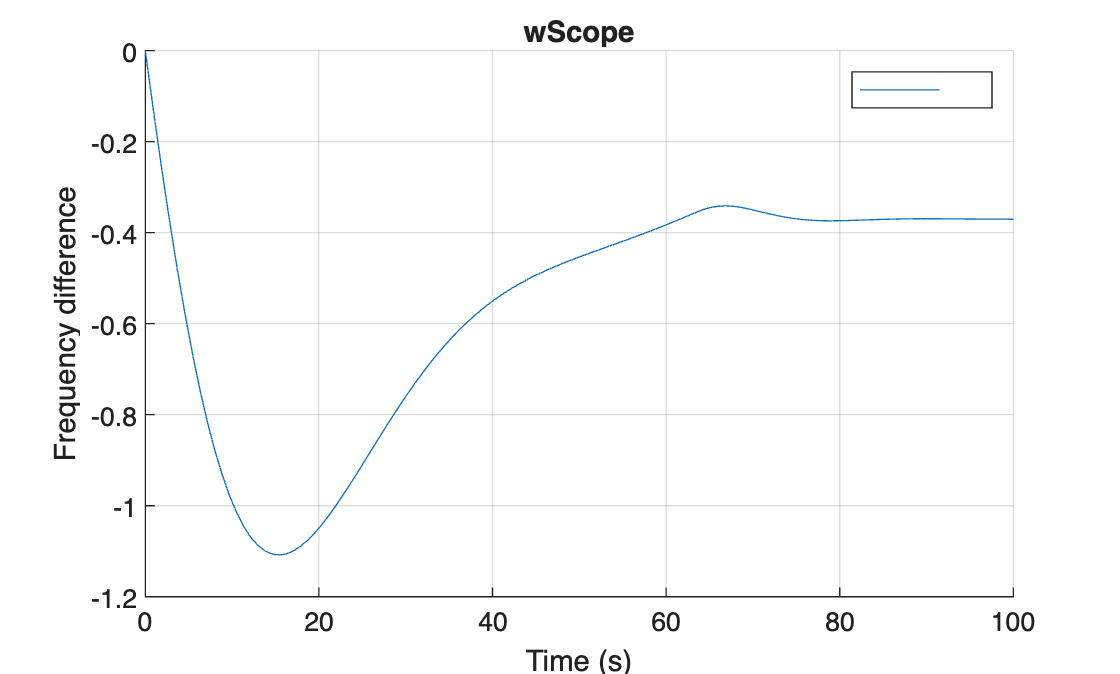


% we do the math in MW rads/s

mdl = 'ass3q1e';
load_system(mdl);
set_param(mdl, 'StopTime', '100');

%% Run simulation
out = sim(mdl);

scopeNames = {'wScope'};

for i = 1:numel(scopeNames)
    name = scopeNames{i};

    % Try to get dataset directly from 'out'
    try
        ds = out.get(name);
    catch
        % Otherwise get it from logsout
        ds = out.logsout.get(name);
    end

    % Plot all signals in this dataset
    figure('Name', name, 'NumberTitle', 'off');
    hold on; grid on;
    for j = 1:ds.numElements
        sig = ds.get(j);
        plot(sig.Values.Time, sig.Values.Data, 'DisplayName', sig.Name);
    end
    xlabel('Time (s)');
    ylabel('Frequency difference');
    title(name);
    legend('show');
end

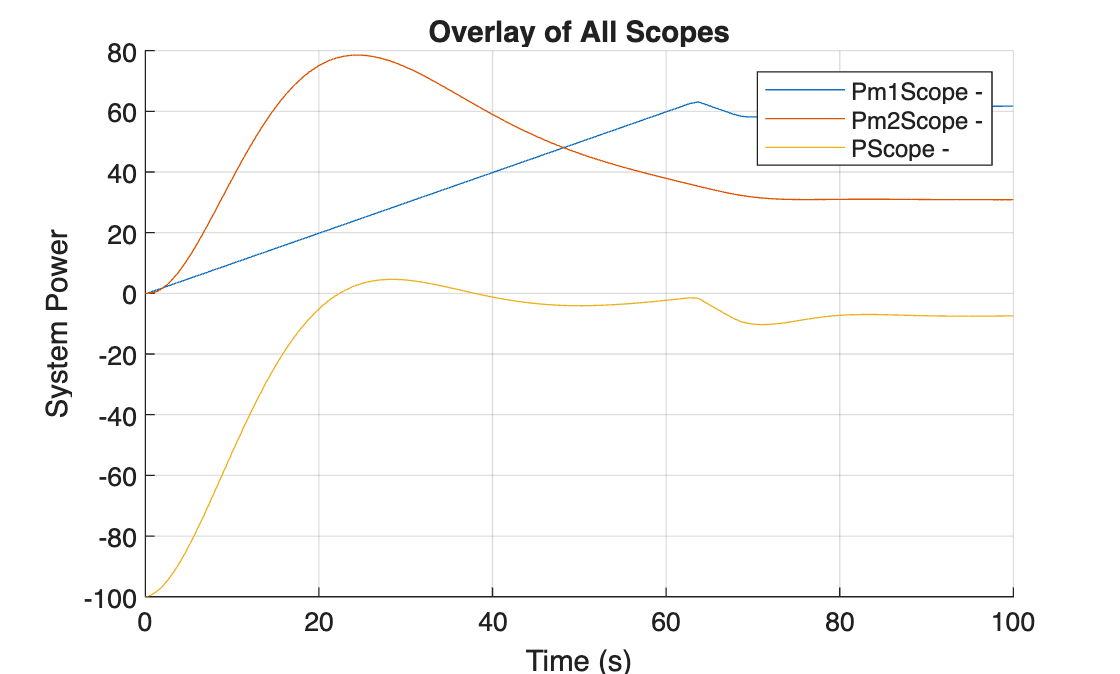


scopeNames = {'Pm1Scope','Pm2Scope','PScope'};

figure; hold on; grid on;

for i = 1:numel(scopeNames)
    name = scopeNames{i};

    % Try to get dataset directly from 'out'
    try
        ds = out.get(name);
    catch
        % Otherwise get it from logsout
        ds = out.logsout.get(name);
    end

    % Plot each signal in this scope
    for j = 1:ds.numElements
        sig = ds.get(j);
        plot(sig.Values.Time, sig.Values.Data, 'DisplayName', [name ' - ' sig.Name]);
    end
end

xlabel('Time (s)');
ylabel('System Power');
title('Overlay of All Scopes');
legend('show', 'Interpreter', 'none');


% we can observe that setting a slew rate limit of 1 causes
% the frequency to have a nadir of ~-1.1 HZ so 58.9Hz. We also see that
% it takes longer for the freq stabilize. 
% P2 does most of th work to compensate for tehe difference initially and
% then it goes down as P1 ramps up. the total power P stabilizes closer to 0 until 60s but then drops 

% Question 2
% tuning K

Tch1 = 3 %s

Tch1 = 3

Tch2 = 8 %s

Tch2 = 8


Tg1 = 0.25

Tg1 = 0.2500

Tg2 = 0.50

Tg2 = 0.5000


R1 = 0.0060 * 2 * pi % rad / s MW 

R1 = 0.0377

R2 = 0.0120 * 2 * pi % rad / s MW 

R2 = 0.0754


M = 1.1141e+08 / 10^6 % convert to MW s^2 / rad

M = 111.4100

D = 20 / ( 2 * pi) % MW s / rad

D = 3.1831


K = 0.3

K = 0.3000

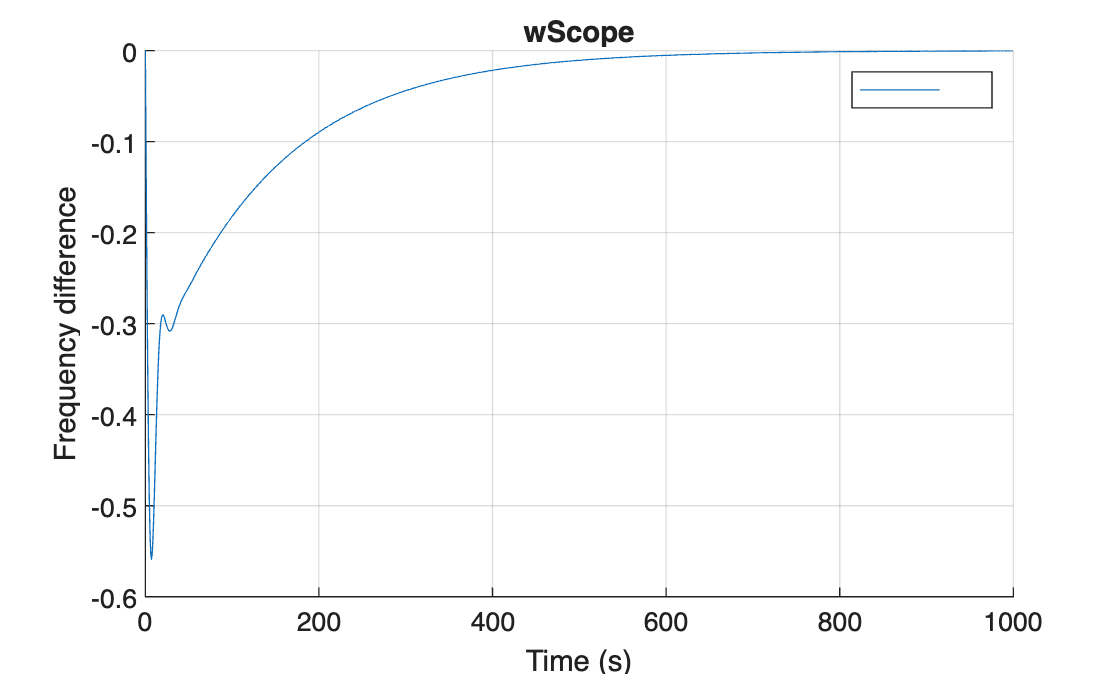

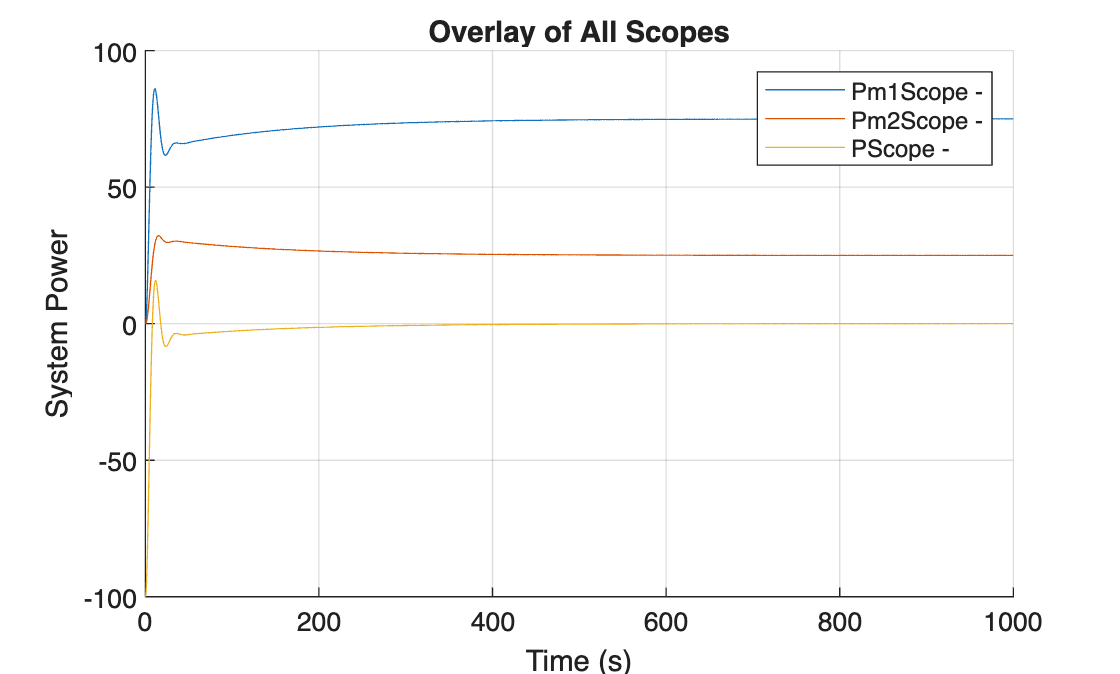

K = 0.2500

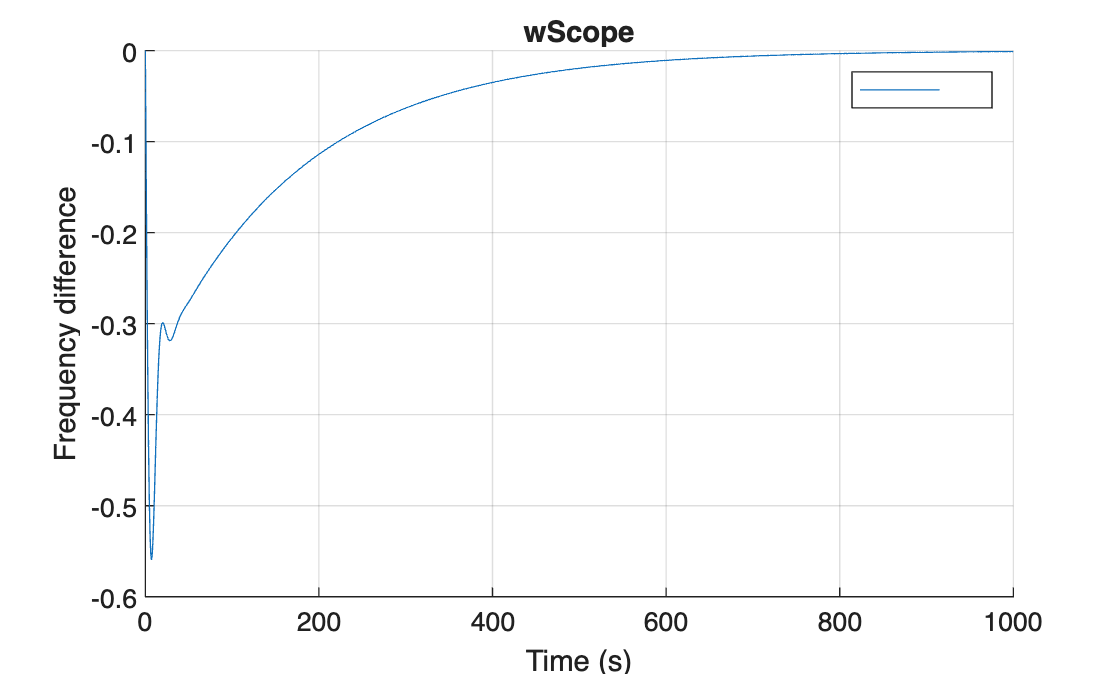

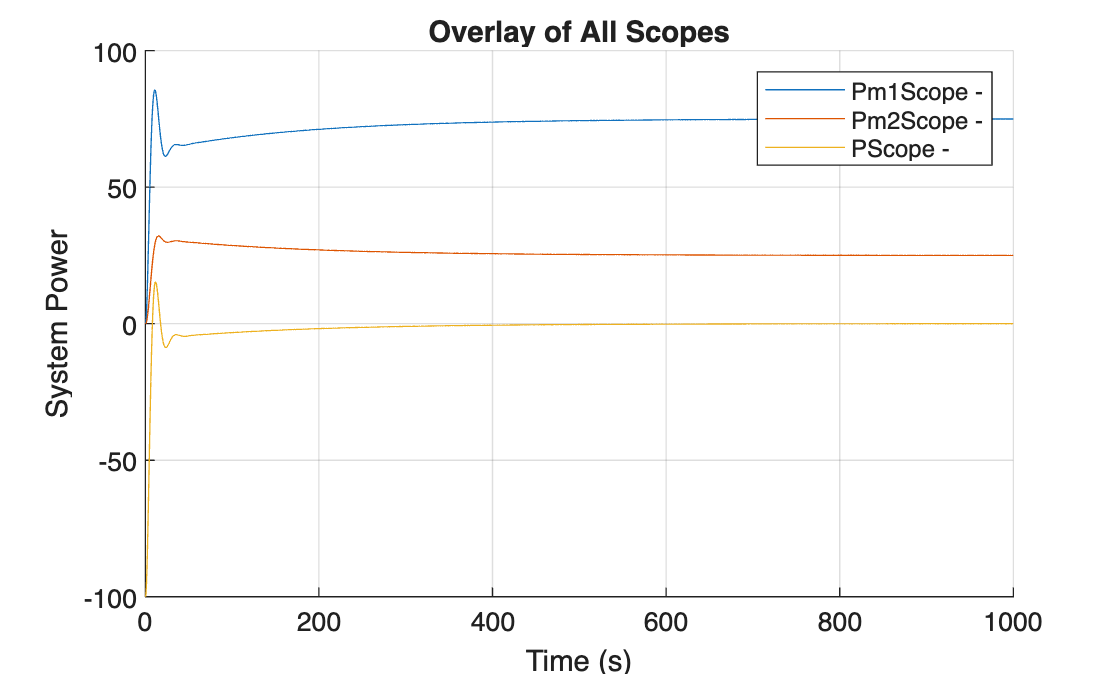

K = 0.2000

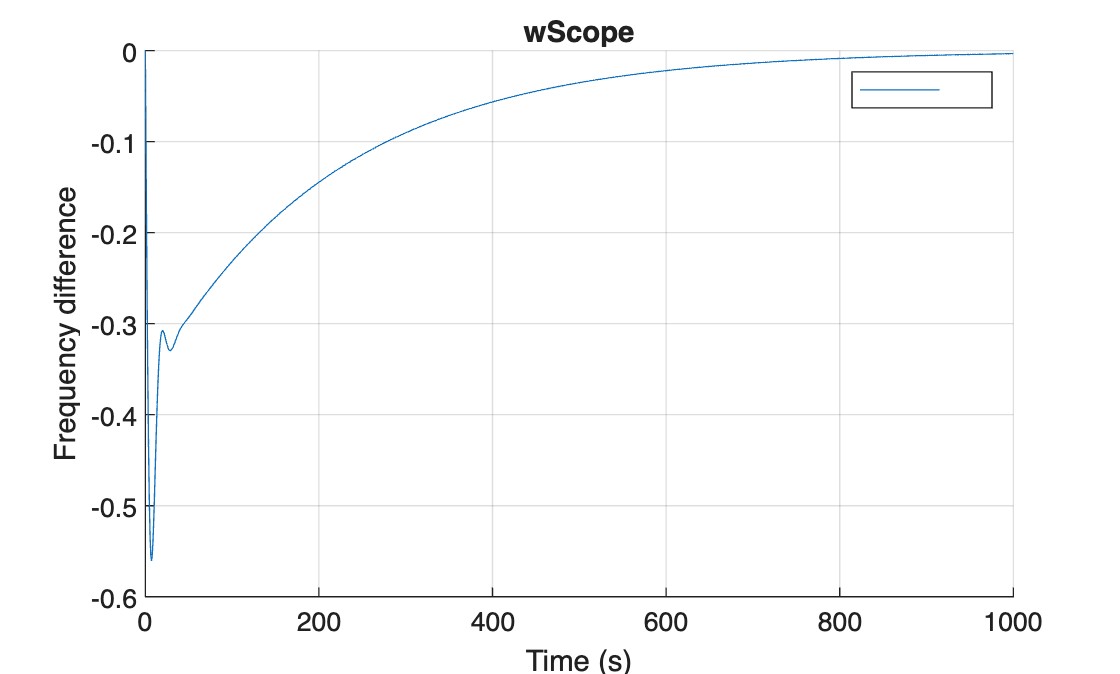

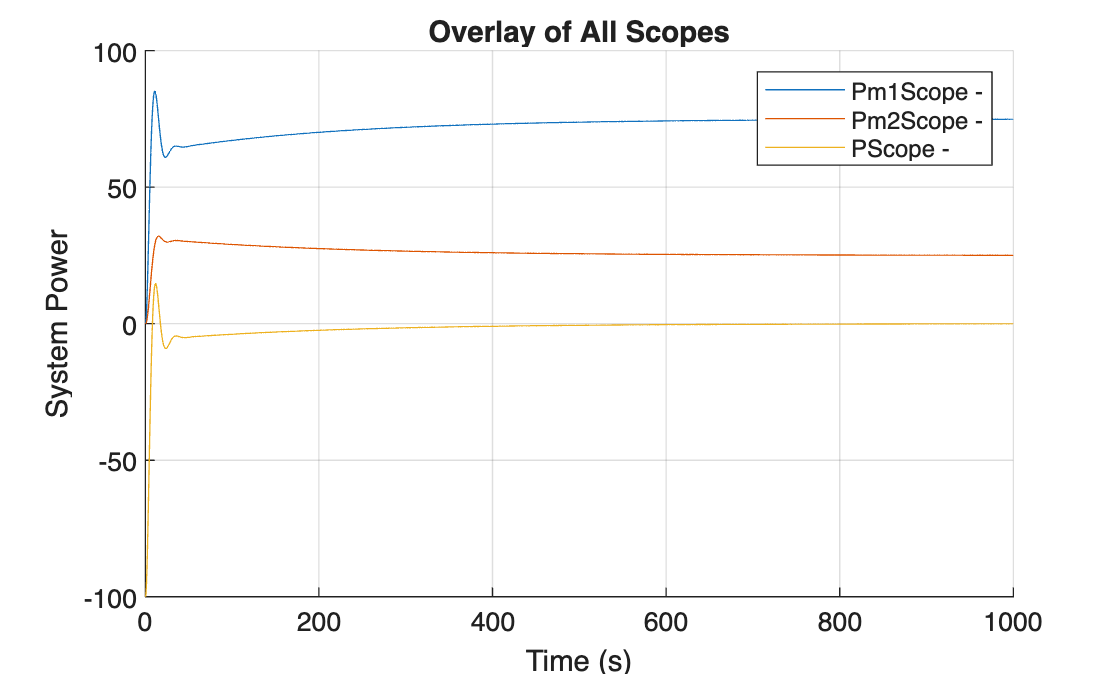

K = 0.1500

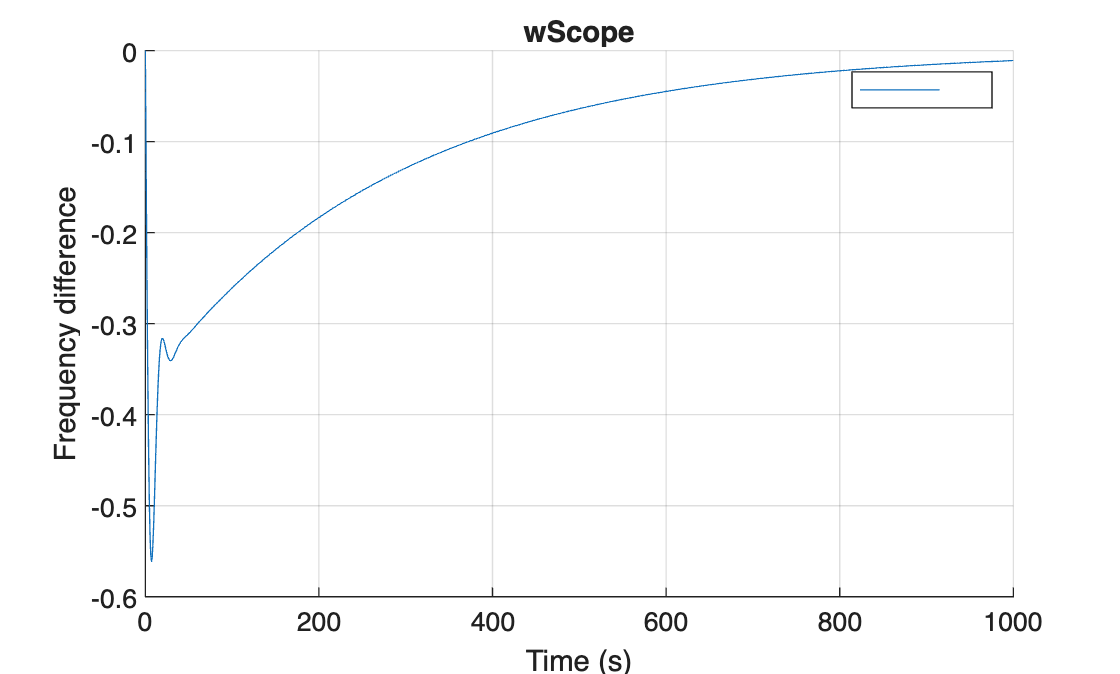

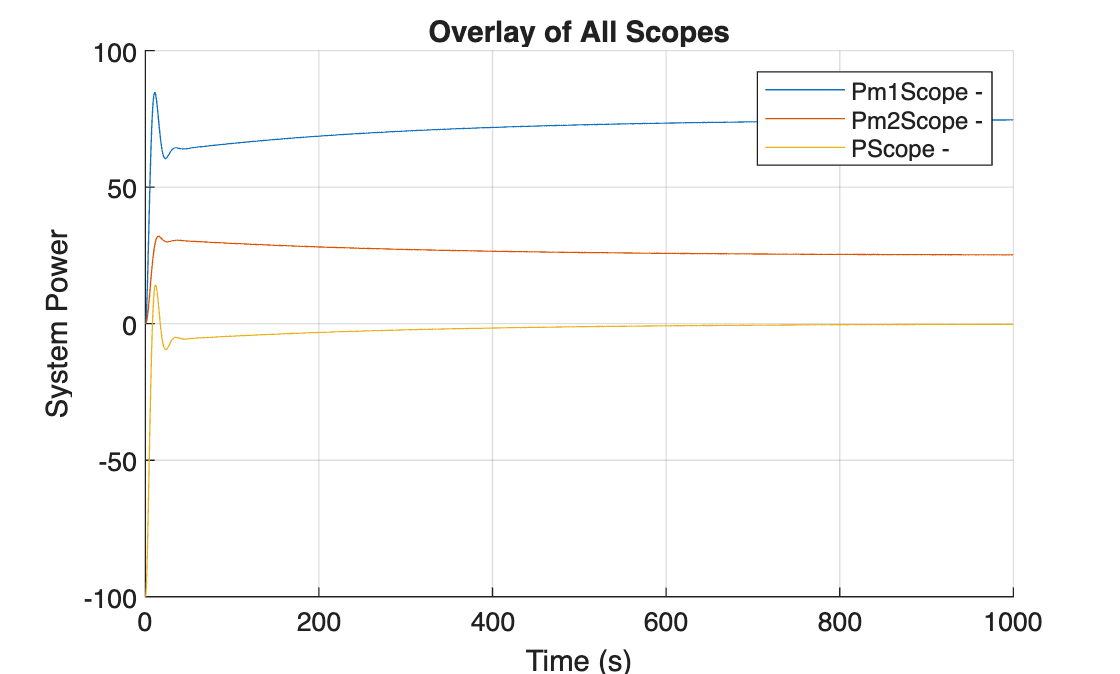

K = 0.1000

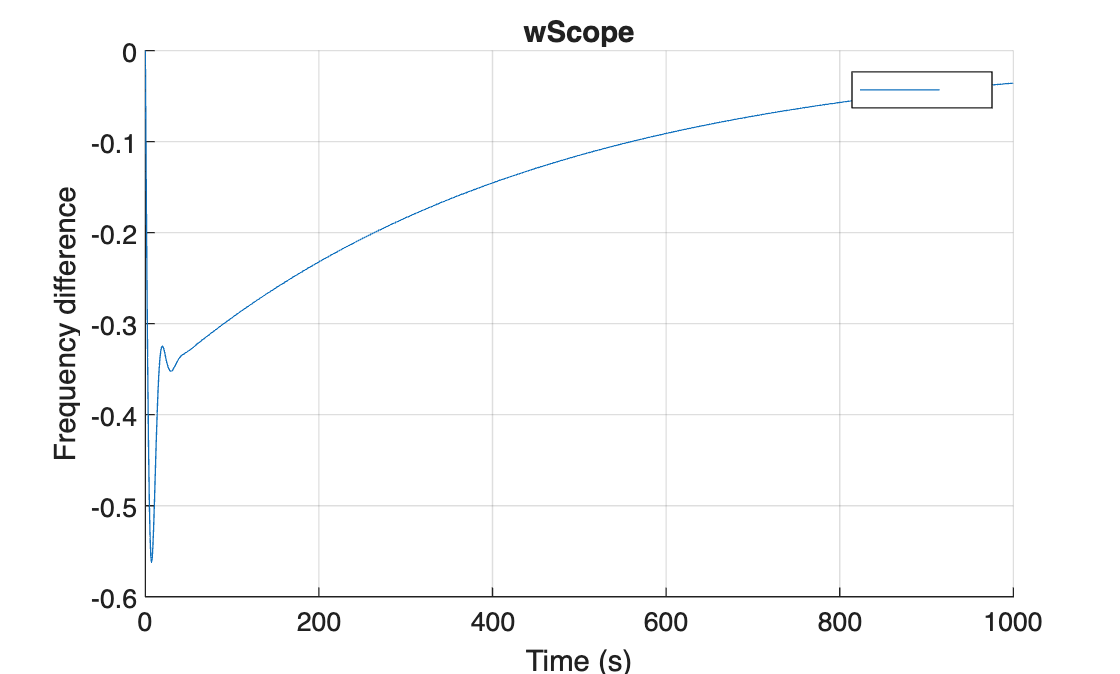

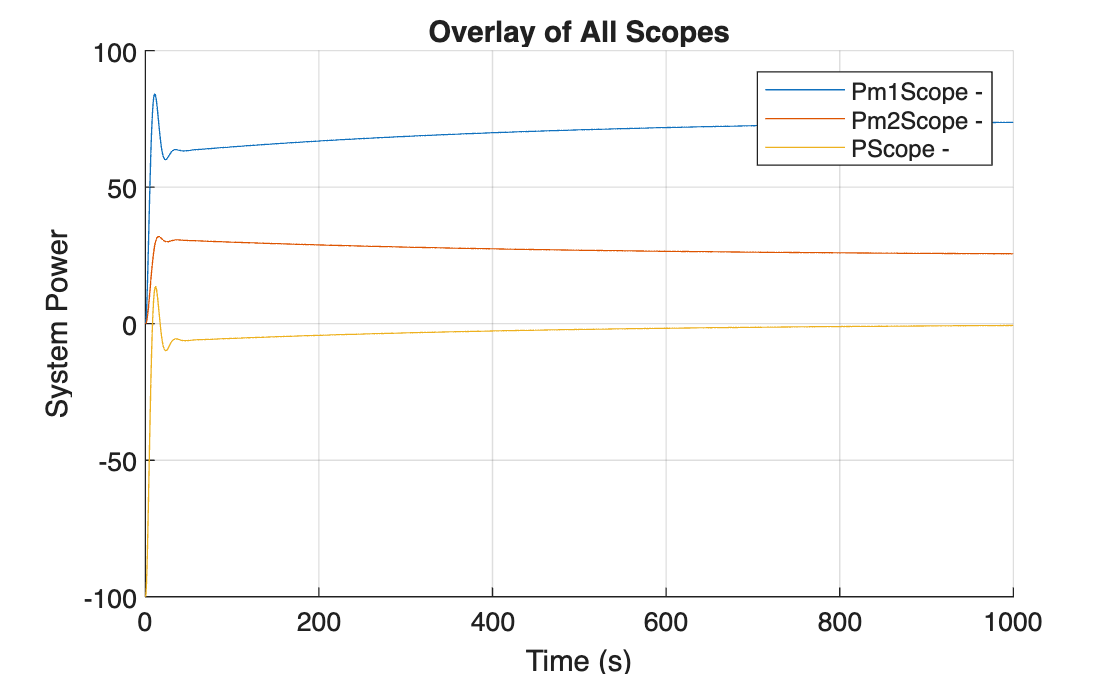

K = 0.0500

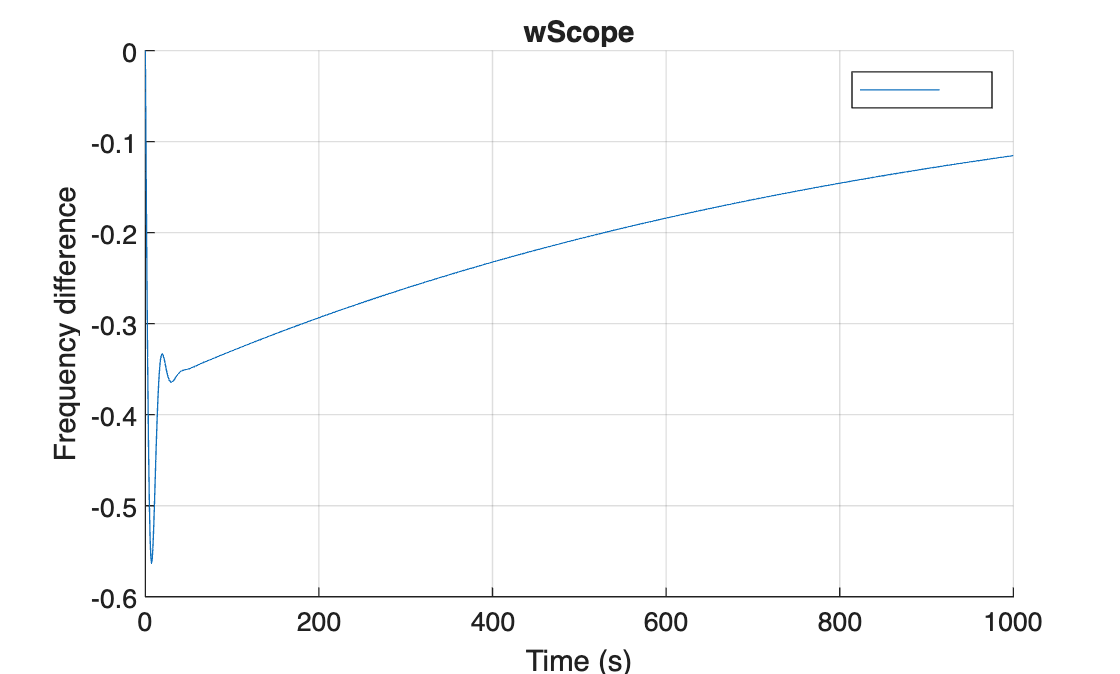

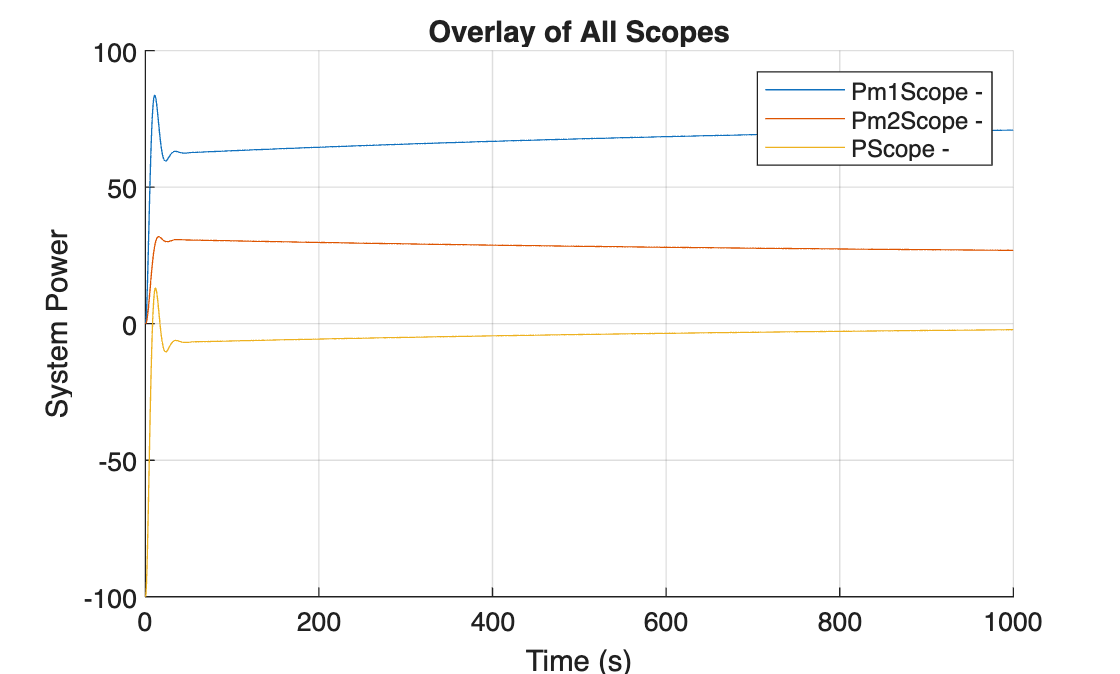

K = 1.3878e-17

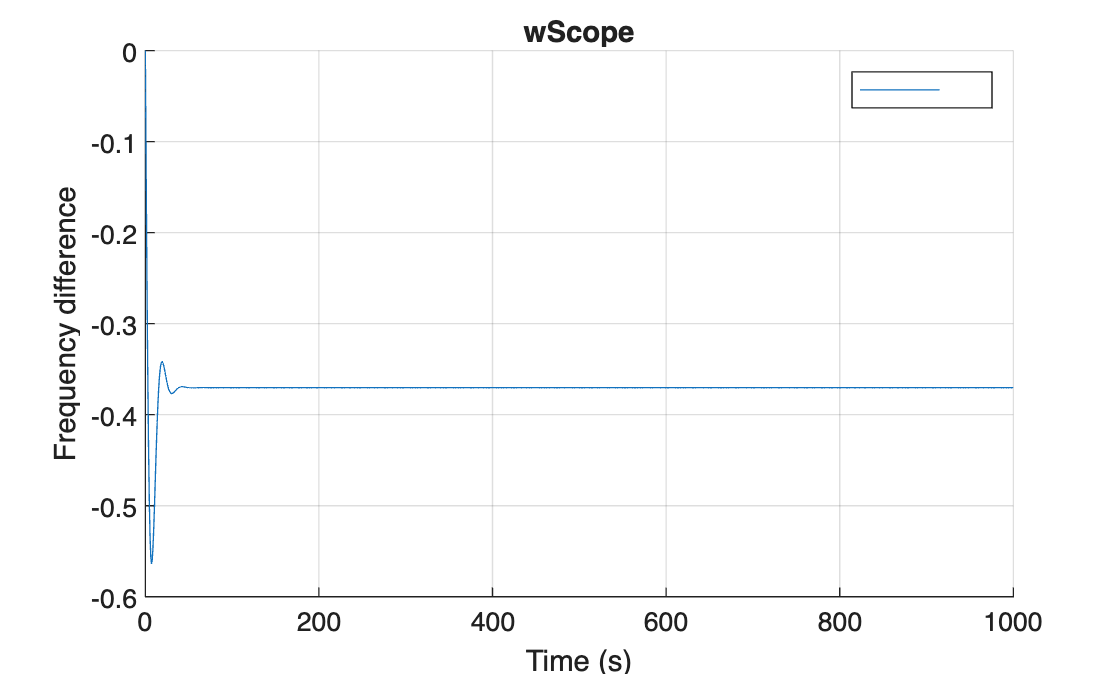

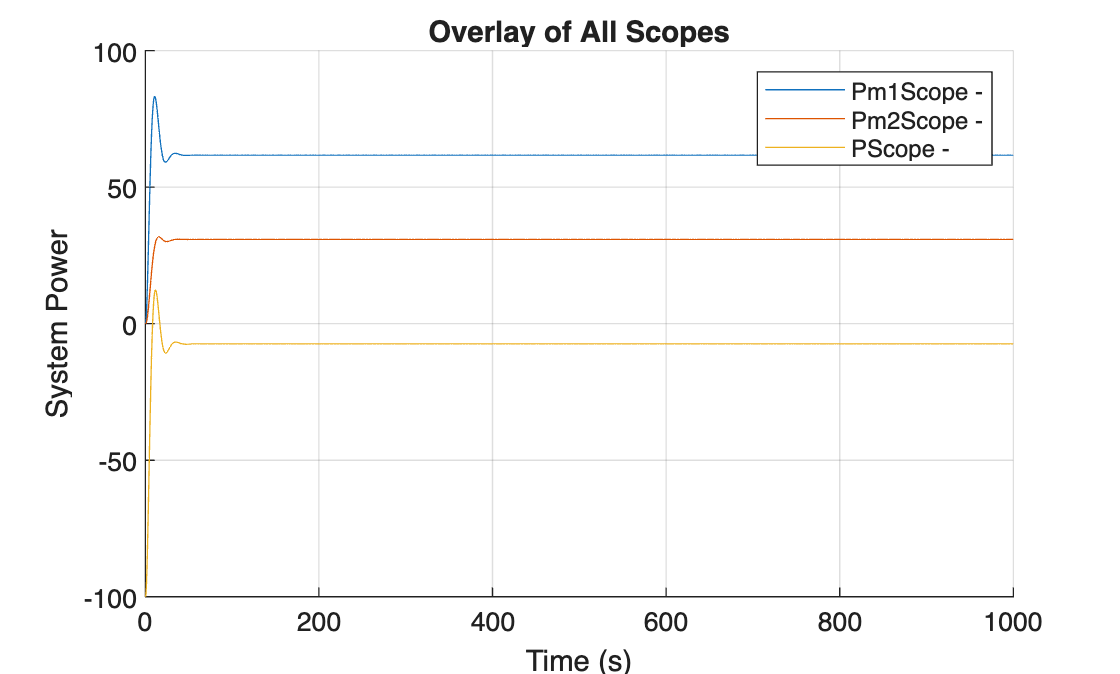

K = -0.0500

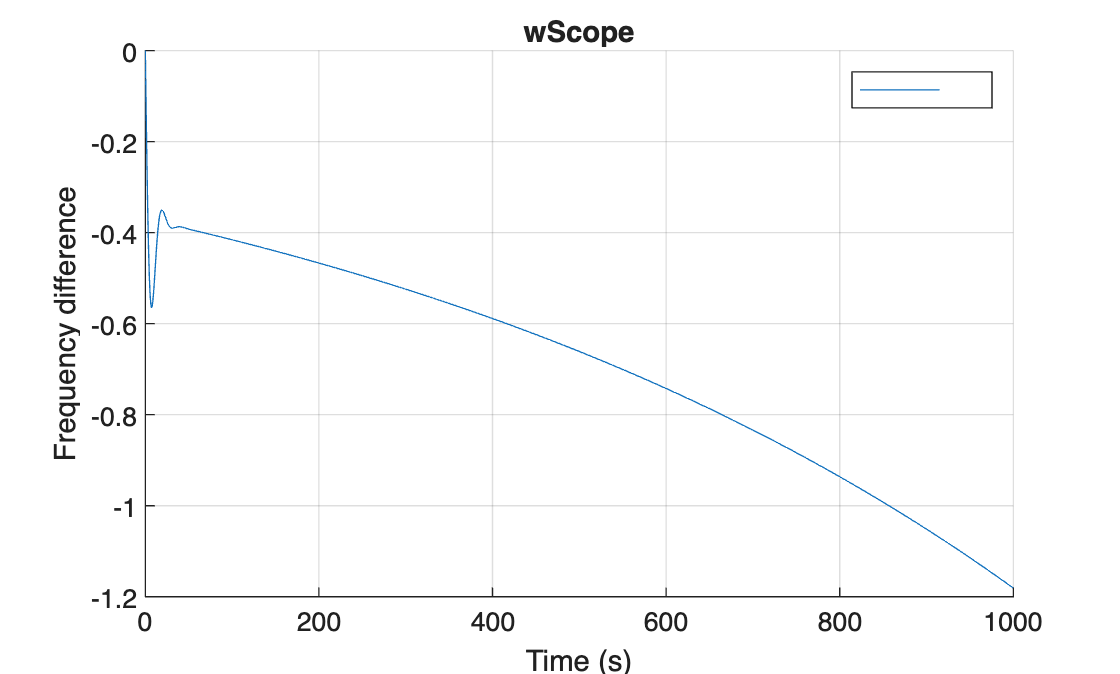

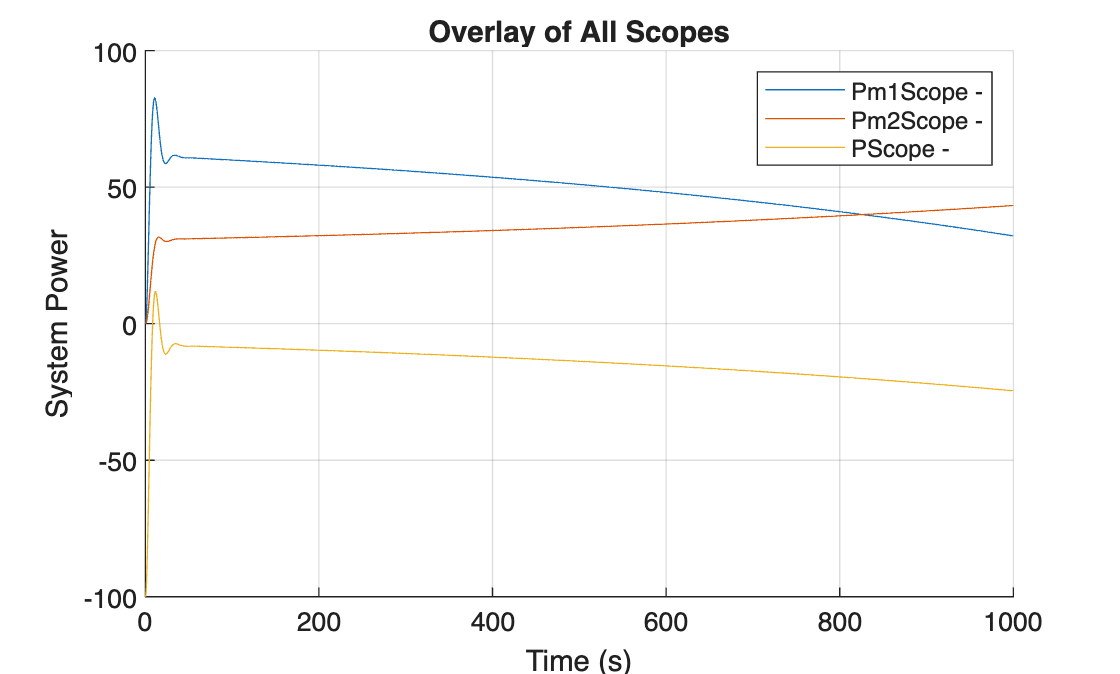

K = -0.1000

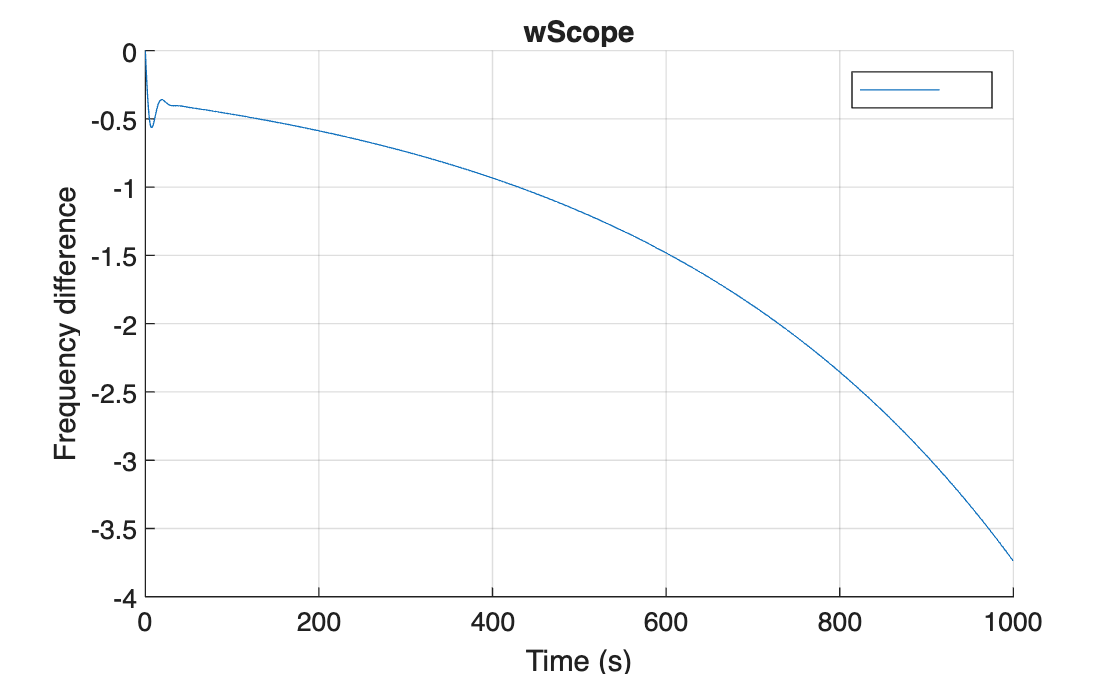

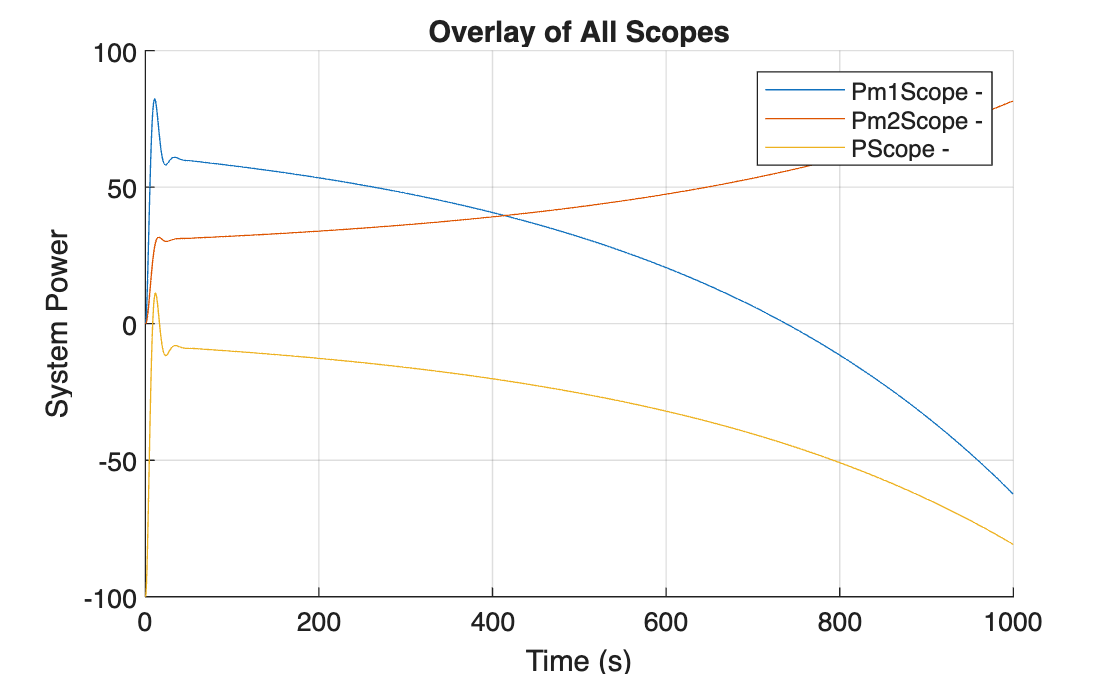

K = -0.1500

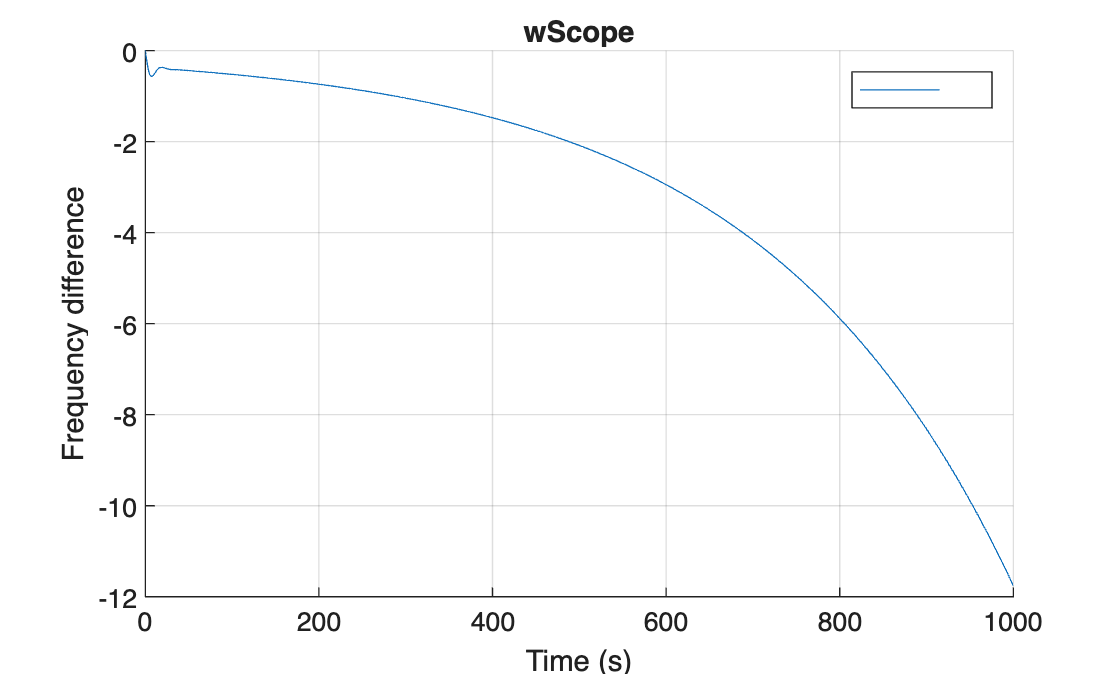

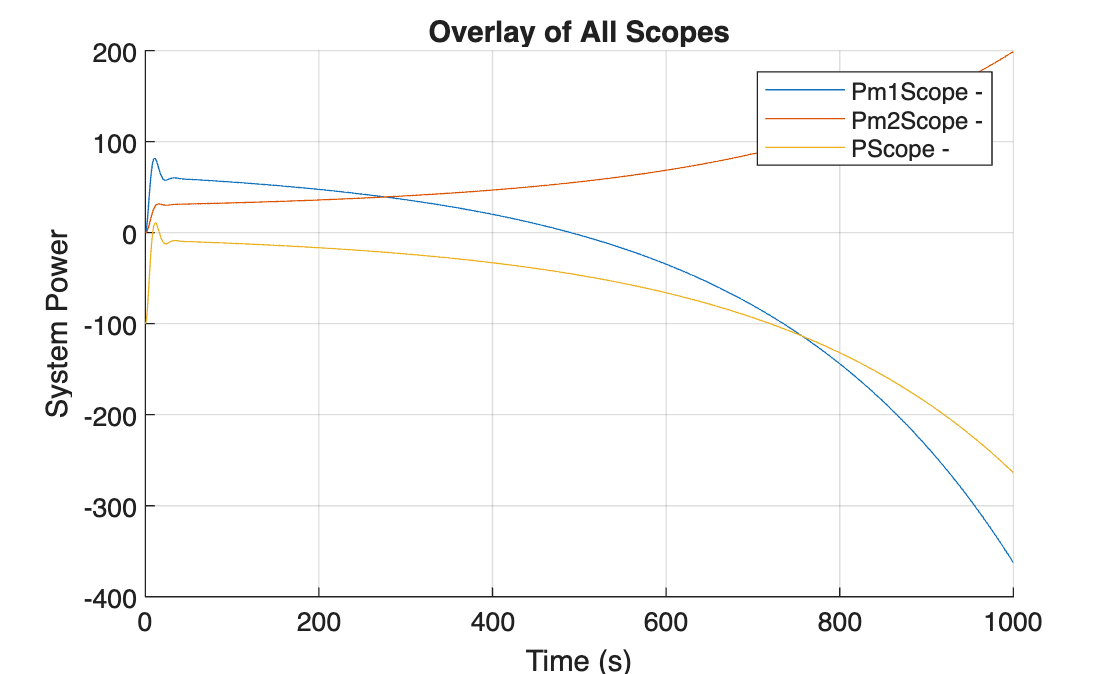

K = -0.2000


% we do the math in MW rads/s

for i = 1:10

    mdl = 'ass3q2';
    load_system(mdl);
    set_param(mdl, 'StopTime', '1000');
    
    %% Run simulation
    out = sim(mdl);
    
    scopeNames = {'wScope'};
    
    for i = 1:numel(scopeNames)
        name = scopeNames{i};
    
        % Try to get dataset directly from 'out'
        try
            ds = out.get(name);
        catch
            % Otherwise get it from logsout
            ds = out.logsout.get(name);
        end
    
        % Plot all signals in this dataset
        figure('Name', name, 'NumberTitle', 'off');
        hold on; grid on;
        for j = 1:ds.numElements
            sig = ds.get(j);
            plot(sig.Values.Time, sig.Values.Data, 'DisplayName', sig.Name);
        end
        xlabel('Time (s)');
        ylabel('Frequency difference');
        title(name);
        legend('show');
    end

    scopeNames = {'Pm1Scope','Pm2Scope','PScope'};

    figure; hold on; grid on;
    
    for i = 1:numel(scopeNames)
        name = scopeNames{i};
    
        % Try to get dataset directly from 'out'
        try
            ds = out.get(name);
        catch
            % Otherwise get it from logsout
            ds = out.logsout.get(name);
        end
    
        % Plot each signal in this scope
        for j = 1:ds.numElements
            sig = ds.get(j);
            plot(sig.Values.Time, sig.Values.Data, 'DisplayName', [name ' - ' sig.Name]);
        end
    end

    xlabel('Time (s)');
    ylabel('System Power');
    title('Overlay of All Scopes');
    legend('show', 'Interpreter', 'none');

    K = K - .05
end

% Question 2
% after selecting K

Tch1 = 3 %s

Tch1 = 3

Tch2 = 8 %s

Tch2 = 8


Tg1 = 0.25

Tg1 = 0.2500

Tg2 = 0.50

Tg2 = 0.5000


R1 = 0.0060 * 2 * pi % rad / s MW 

R1 = 0.0377

R2 = 0.0120 * 2 * pi % rad / s MW 

R2 = 0.0754


M = 1.1141e+08 / 10^6 % convert to MW s^2 / rad

M = 111.4100

D = 20 / ( 2 * pi) % MW s / rad

D = 3.1831


K = .25 %MW

K = 0.2500


% we do the math in MW rads/s


mdl = 'ass3q2';
load_system(mdl);
min15 = 60*15

min15 = 900

set_param(mdl, 'StopTime', '1000');

%% Run simulation
out = sim(mdl);

scopeNames = {'wScope'};

for i = 1:numel(scopeNames)
    name = scopeNames{i};

    % Try to get dataset directly from 'out'
    try
        ds = out.get(name);
    catch
        % Otherwise get it from logsout
        ds = out.logsout.get(name);
    end

    % Plot all signals in this dataset
    figure('Name', name, 'NumberTitle', 'off');
    hold on; grid on;
    for j = 1:ds.numElements
        sig = ds.get(j);
        plot(sig.Values.Time, sig.Values.Data, 'DisplayName', sig.Name);
    end
    xlabel('Time (s)');
    ylabel('Frequency difference');
    title(name);
    legend('show');
end


scopeNames = {'Pm1Scope','Pm2Scope','PScope'};

figure; hold on; grid on;

for i = 1:numel(scopeNames)
    name = scopeNames{i};

    % Try to get dataset directly from 'out'
    try
        ds = out.get(name);
    catch
        % Otherwise get it from logsout
        ds = out.logsout.get(name);
    end

    % Plot each signal in this scope
    for j = 1:ds.numElements
        sig = ds.get(j);
        plot(sig.Values.Time, sig.Values.Data, 'DisplayName', [name ' - ' sig.Name]);
    end
end

xlabel('Time (s)');
ylabel('System Power');
title('Overlay of All Scopes');
legend('show', 'Interpreter', 'none');


% Playing around with K, we can stick K = .25 we have one small osciliation initially
% and then it slowly ramps back to 60 Hz at around 850 seconds
% there is also minimal ocsilation in the steady state

% Question 3

Tch1 = 3 %s

Tch1 = 3

Tch2 = 8 %s

Tch2 = 8


Tg1 = 0.25

Tg1 = 0.2500

Tg2 = 0.50

Tg2 = 0.5000


R1 = 0.0060 * 2 * pi % rad / s MW 

R1 = 0.0377

R2 = 0.0120 * 2 * pi % rad / s MW 

R2 = 0.0754


Mred = 1.1141e+08 / 10^6 * .6 % convert to MW s^2 / rad

Mred = 66.8460

Dred = 20 / ( 2 * pi) * .5 % MW s / rad

Dred = 1.5915


K = 0.25 %MW

K = 0.2500

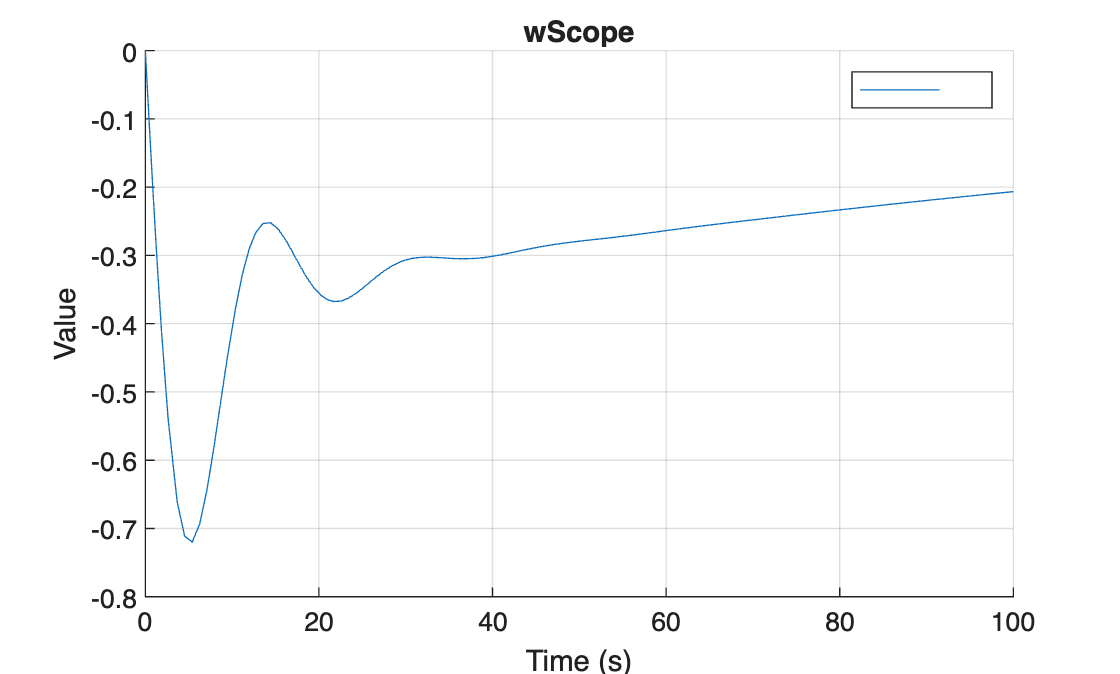


% we do the math in MW rads/s


mdl = 'ass3q3';
load_system(mdl);
set_param(mdl, 'StopTime', '100');

%% Run simulation
out = sim(mdl);

scopeNames = {'wScope'};

for i = 1:numel(scopeNames)
    name = scopeNames{i};

    % Try to get dataset directly from 'out'
    try
        ds = out.get(name);
    catch
        % Otherwise get it from logsout
        ds = out.logsout.get(name);
    end

    % Plot all signals in this dataset
    figure('Name', name, 'NumberTitle', 'off');
    hold on; grid on;
    for j = 1:ds.numElements
        sig = ds.get(j);
        plot(sig.Values.Time, sig.Values.Data, 'DisplayName', sig.Name);
    end
    xlabel('Time (s)');
    ylabel('Value');
    title(name);
    legend('show');
end

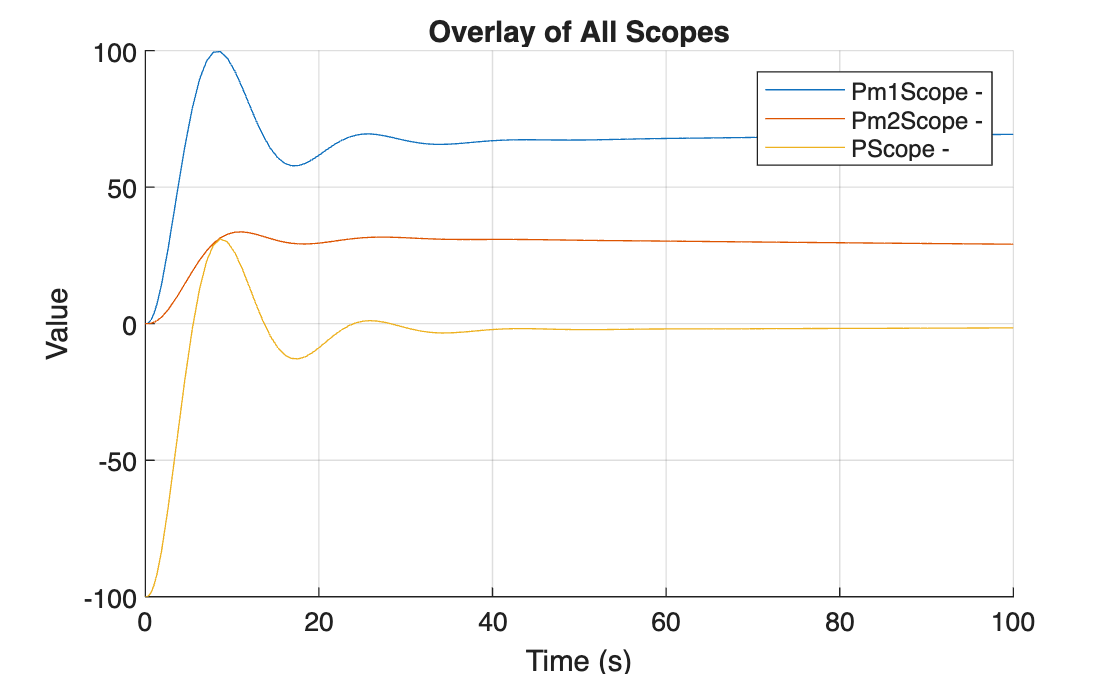


scopeNames = {'Pm1Scope','Pm2Scope','PScope'};

figure; hold on; grid on;

for i = 1:numel(scopeNames)
    name = scopeNames{i};

    % Try to get dataset directly from 'out'
    try
        ds = out.get(name);
    catch
        % Otherwise get it from logsout
        ds = out.logsout.get(name);
    end

    % Plot each signal in this scope
    for j = 1:ds.numElements
        sig = ds.get(j);
        plot(sig.Values.Time, sig.Values.Data, 'DisplayName', [name ' - ' sig.Name]);
    end
end

xlabel('Time (s)');
ylabel('Value');
title('Overlay of All Scopes');
legend('show', 'Interpreter', 'none');


% For the frequency, we get a lower Nadir as well as more oscillations. 
% the same can be said about power, as Ptotal goes to 25Mw in less than 5
% seconds, then goes to -10 MW and then goes bck above around 25 seconds
% then back below. 
% reducing M and D make the drops faster and have more oscilation for the
% same K we selected.

% Question 4 no control

Tch1 = 3 %s

Tch1 = 3

Tch2 = 8 %s

Tch2 = 8


Tg1 = 0.25

Tg1 = 0.2500

Tg2 = 0.50

Tg2 = 0.5000


R1 = 0.0060 * 2 * pi % rad / s MW 

R1 = 0.0377

R2 = 0.0120 * 2 * pi % rad / s MW 

R2 = 0.0754



M = 1.1141e+08 / 10^6 % convert to MW s^2 / rad

M = 111.4100

D = 20 / ( 2 * pi) % MW s / rad

D = 3.1831


B = 1/R1 + 1/R2 + D % Mw

B = 42.9718


K = .25 

K = 0.2500

T = 20000

T = 20000

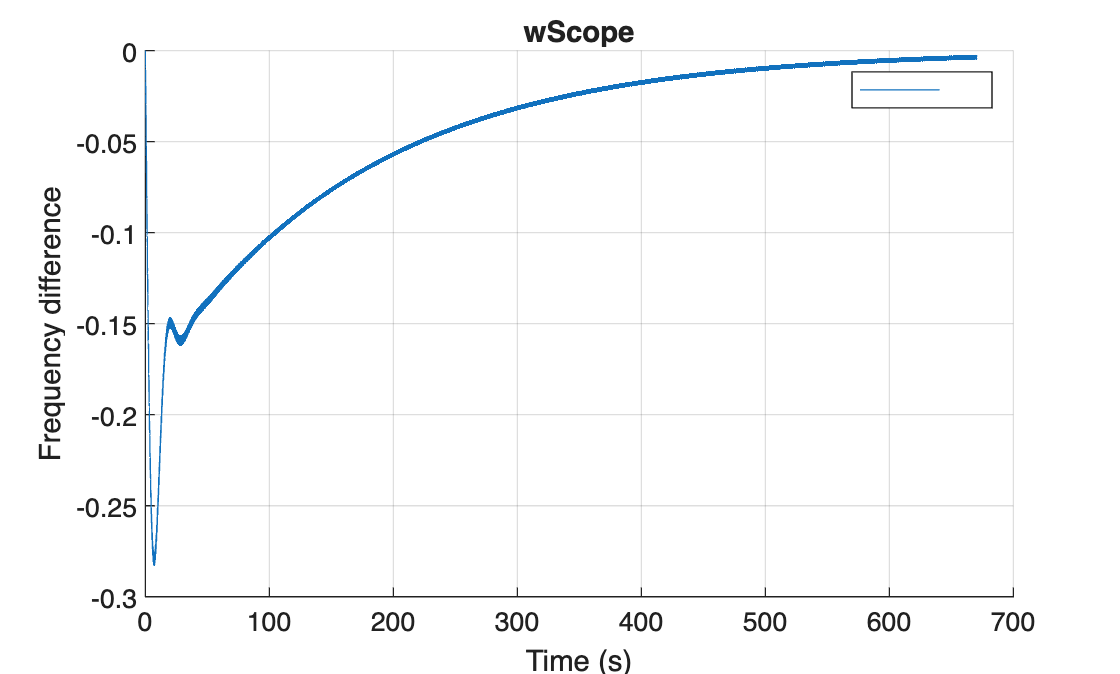

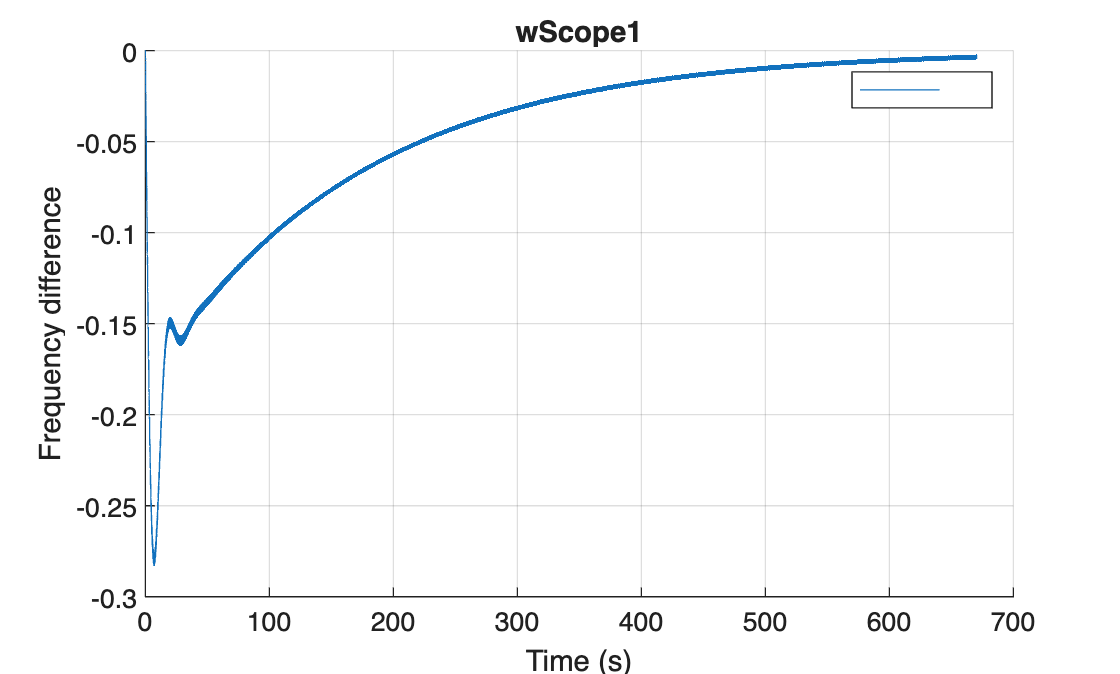

% we do the math in MW rads/s


mdl = 'ass3q4';
load_system(mdl);
set_param(mdl, 'StopTime', '1200');

%% Run simulation
out = sim(mdl);

scopeNames = {'wScope', 'wScope1'};

for i = 1:numel(scopeNames)
    name = scopeNames{i};

    % Try to get dataset directly from 'out'
    try
        ds = out.get(name);
    catch
        % Otherwise get it from logsout
        ds = out.logsout.get(name);
    end

    % Plot all signals in this dataset
    figure('Name', name, 'NumberTitle', 'off');
    hold on; grid on;
    for j = 1:ds.numElements
        sig = ds.get(j);
        plot(sig.Values.Time, sig.Values.Data, 'DisplayName', sig.Name);
    end
    xlabel('Time (s)');
    ylabel('Frequency difference');
    title(name);
    legend('show');
end

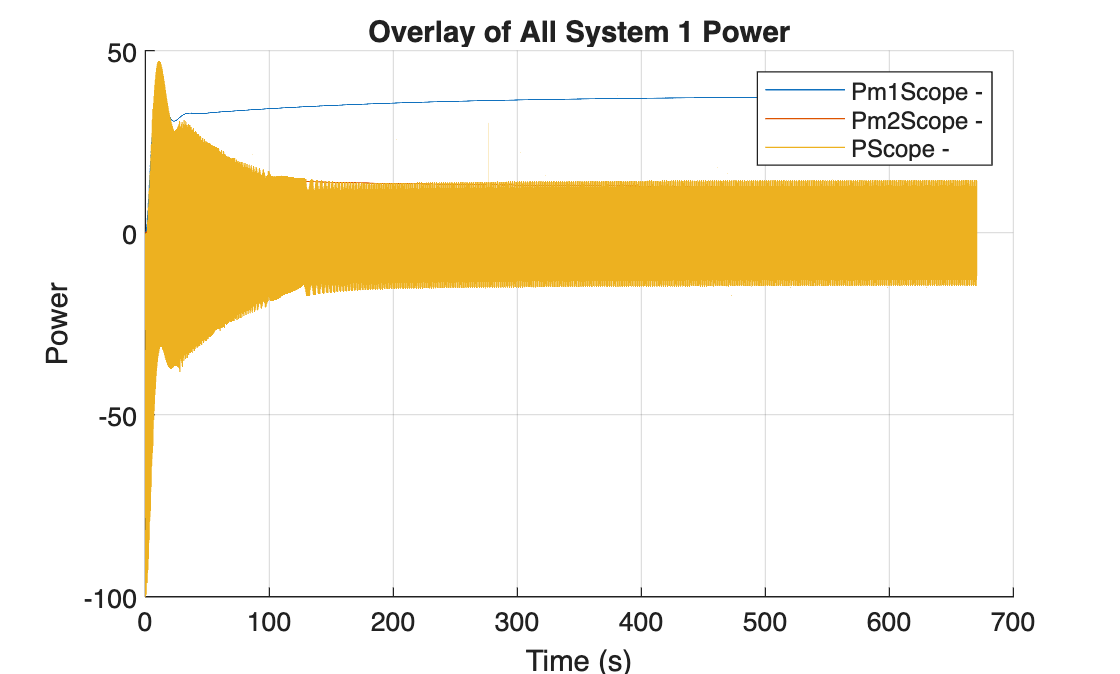


scopeNames = {'Pm1Scope','Pm2Scope','PScope'};

figure; hold on; grid on;

for i = 1:numel(scopeNames)
    name = scopeNames{i};

    % Try to get dataset directly from 'out'
    try
        ds = out.get(name);
    catch
        % Otherwise get it from logsout
        ds = out.logsout.get(name);
    end

    % Plot each signal in this scope
    for j = 1:ds.numElements
        sig = ds.get(j);
        plot(sig.Values.Time, sig.Values.Data, 'DisplayName', [name ' - ' sig.Name]);
    end
end

xlabel('Time (s)');
ylabel('Power');
title('Overlay of All System 1 Power');
legend('show', 'Interpreter', 'none');

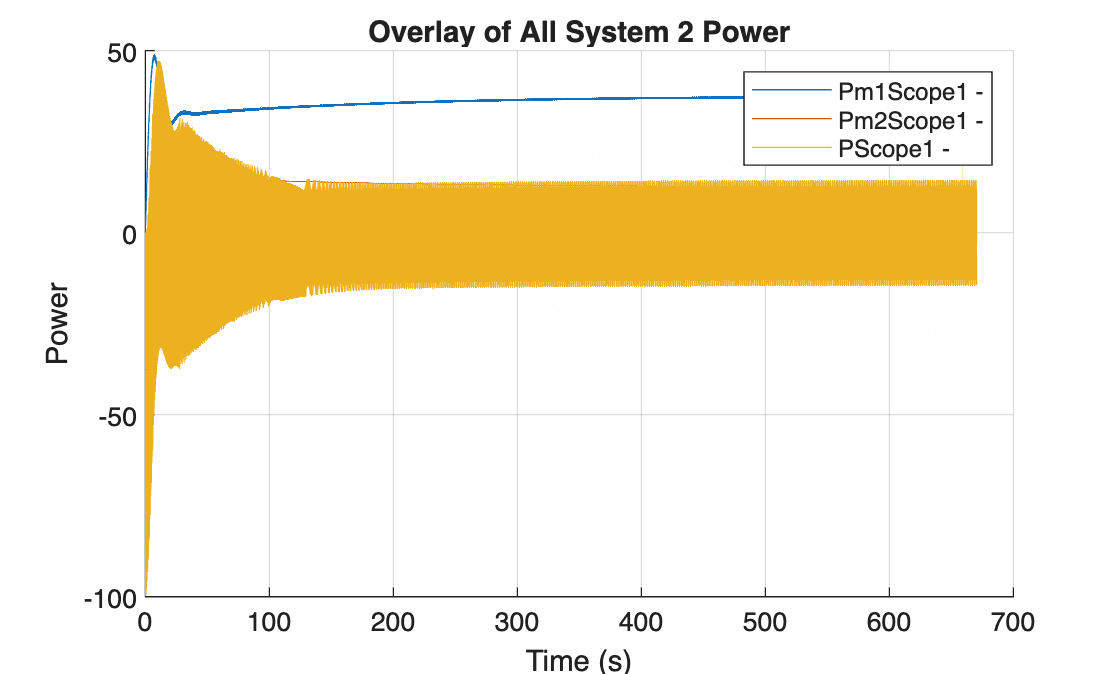


scopeNames = {'Pm1Scope1','Pm2Scope1','PScope1'};

figure; hold on; grid on;

for i = 1:numel(scopeNames)
    name = scopeNames{i};

    % Try to get dataset directly from 'out'
    try
        ds = out.get(name);
    catch
        % Otherwise get it from logsout
        ds = out.logsout.get(name);
    end

    % Plot each signal in this scope
    for j = 1:ds.numElements
        sig = ds.get(j);
        plot(sig.Values.Time, sig.Values.Data, 'DisplayName', [name ' - ' sig.Name]);
    end
end


xlabel('Time (s)');
ylabel('Power');
title('Overlay of All System 2 Power');
legend('show', 'Interpreter', 'none');

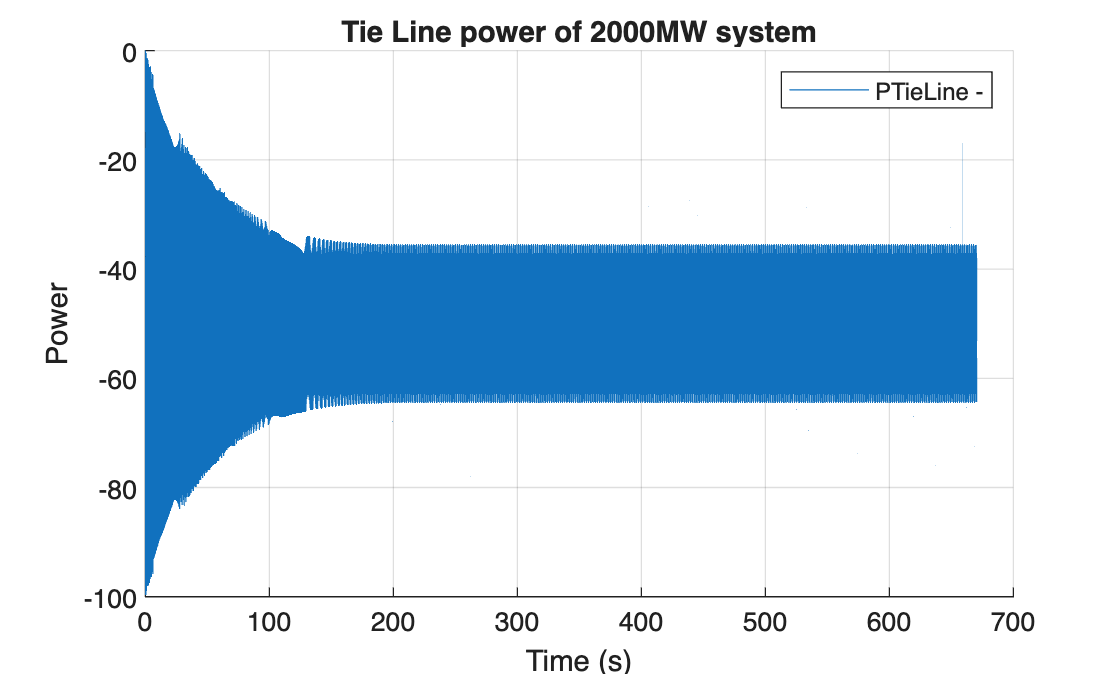



scopeNames = {'PTieLine'};

figure; hold on; grid on;

for i = 1:numel(scopeNames)
    name = scopeNames{i};

    % Try to get dataset directly from 'out'
    try
        ds = out.get(name);
    catch
        % Otherwise get it from logsout
        ds = out.logsout.get(name);
    end

    % Plot each signal in this scope
    for j = 1:ds.numElements
        sig = ds.get(j);
        plot(sig.Values.Time, sig.Values.Data, 'DisplayName', [name ' - ' sig.Name]);
    end
end


xlabel('Time (s)');
ylabel('Power');
title('Tie Line power of 2000MW system');
legend('show', 'Interpreter', 'none');


% We can see that the frequencygoes back to 0, but the tie line power
% ocsillated around -50 MW.

% Question 4 with control
Tch1 = 3 %s

Tch1 = 3

Tch2 = 8 %s

Tch2 = 8


Tg1 = 0.25

Tg1 = 0.2500

Tg2 = 0.50

Tg2 = 0.5000


R1 = 0.0060 * 2 * pi % rad / s MW 

R1 = 0.0377

R2 = 0.0120 * 2 * pi % rad / s MW 

R2 = 0.0754



M = 1.1141e+08 / 10^6 % convert to MW s^2 / rad

M = 111.4100

D = 20 / ( 2 * pi) % MW s / rad

D = 3.1831


B = 1/R1 + 1/R2 + D % Mw

B = 42.9718


K = .1 

K = 0.1000

T = 20000

T = 20000

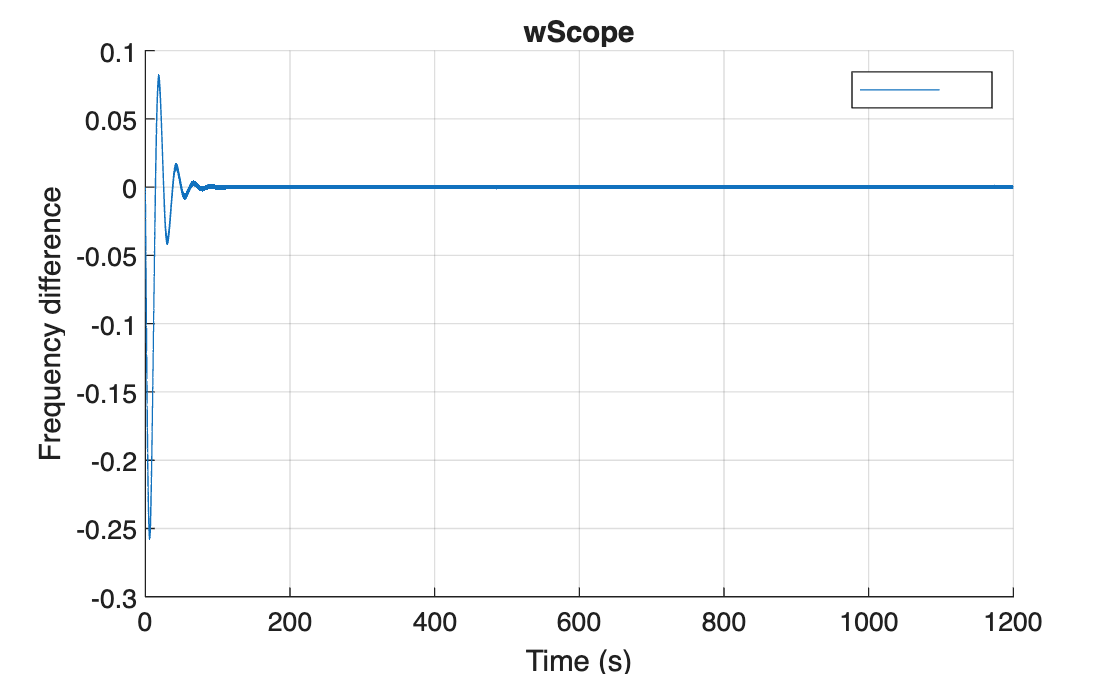

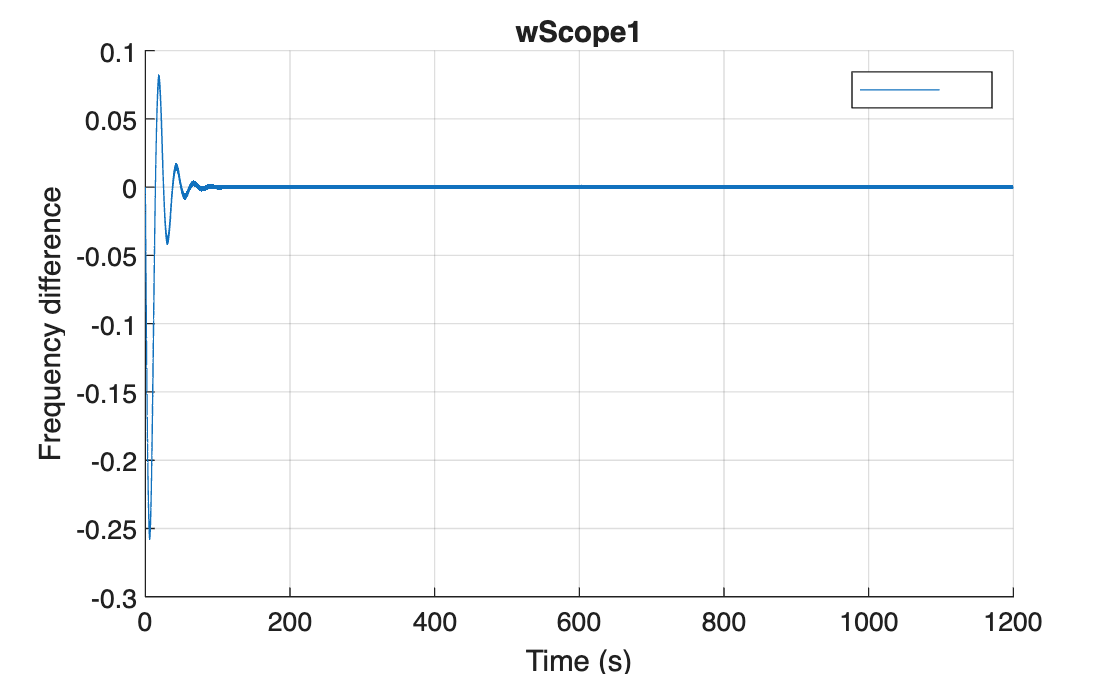

% we do the math in MW rads/s


mdl = 'ass3q4Control';
load_system(mdl);
set_param(mdl, 'StopTime', '1200');

%% Run simulation
out = sim(mdl);

scopeNames = {'wScope', 'wScope1'};

for i = 1:numel(scopeNames)
    name = scopeNames{i};

    % Try to get dataset directly from 'out'
    try
        ds = out.get(name);
    catch
        % Otherwise get it from logsout
        ds = out.logsout.get(name);
    end

    % Plot all signals in this dataset
    figure('Name', name, 'NumberTitle', 'off');
    hold on; grid on;
    for j = 1:ds.numElements
        sig = ds.get(j);
        plot(sig.Values.Time, sig.Values.Data, 'DisplayName', sig.Name);
    end
    xlabel('Time (s)');
    ylabel('Frequency difference');
    title(name);
    legend('show');
end

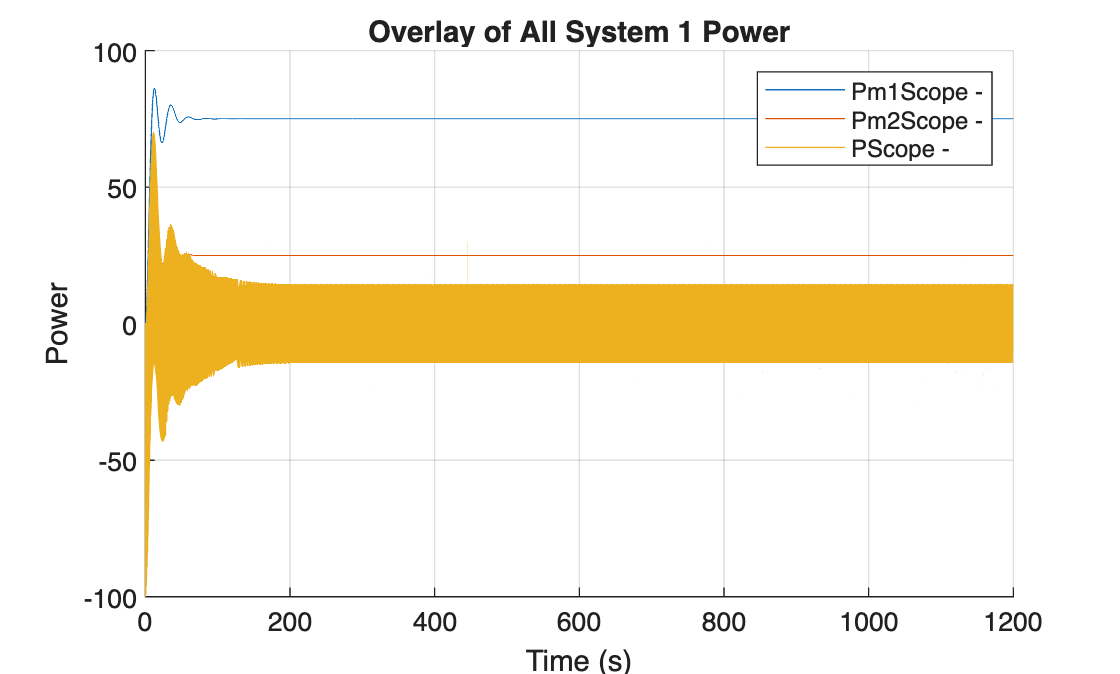


scopeNames = {'Pm1Scope','Pm2Scope','PScope'};

figure; hold on; grid on;

for i = 1:numel(scopeNames)
    name = scopeNames{i};

    % Try to get dataset directly from 'out'
    try
        ds = out.get(name);
    catch
        % Otherwise get it from logsout
        ds = out.logsout.get(name);
    end

    % Plot each signal in this scope
    for j = 1:ds.numElements
        sig = ds.get(j);
        plot(sig.Values.Time, sig.Values.Data, 'DisplayName', [name ' - ' sig.Name]);
    end
end

xlabel('Time (s)');
ylabel('Power');
title('Overlay of All System 1 Power');
legend('show', 'Interpreter', 'none');

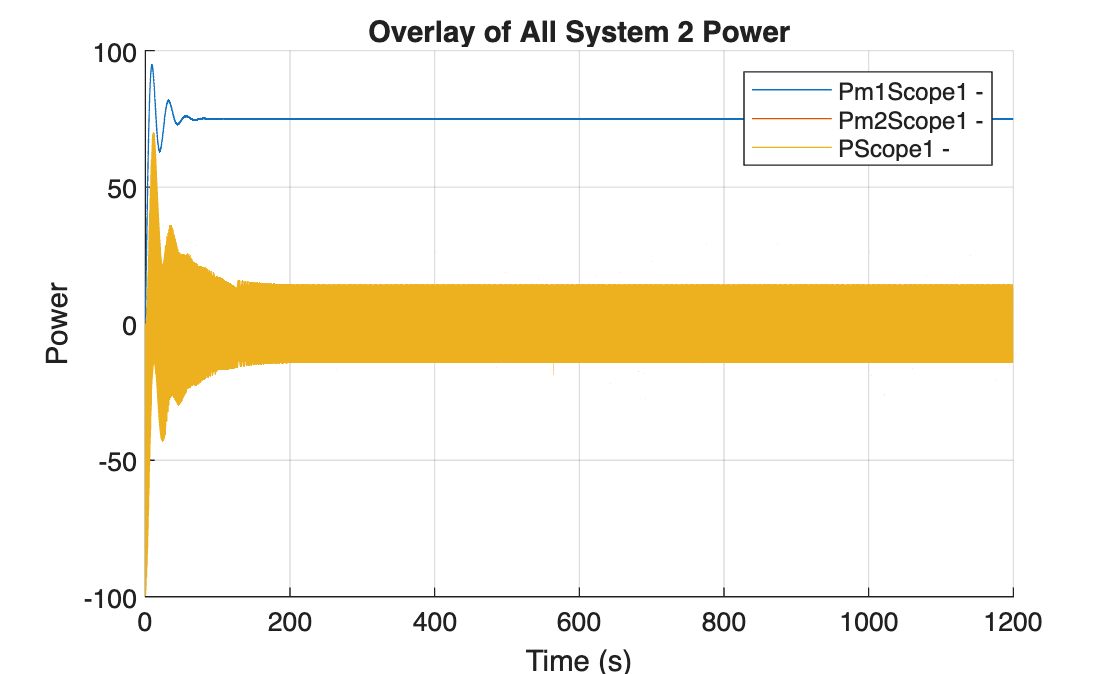


scopeNames = {'Pm1Scope1','Pm2Scope1','PScope1'};

figure; hold on; grid on;

for i = 1:numel(scopeNames)
    name = scopeNames{i};

    % Try to get dataset directly from 'out'
    try
        ds = out.get(name);
    catch
        % Otherwise get it from logsout
        ds = out.logsout.get(name);
    end

    % Plot each signal in this scope
    for j = 1:ds.numElements
        sig = ds.get(j);
        plot(sig.Values.Time, sig.Values.Data, 'DisplayName', [name ' - ' sig.Name]);
    end
end


xlabel('Time (s)');
ylabel('Power');
title('Overlay of All System 2 Power');
legend('show', 'Interpreter', 'none');

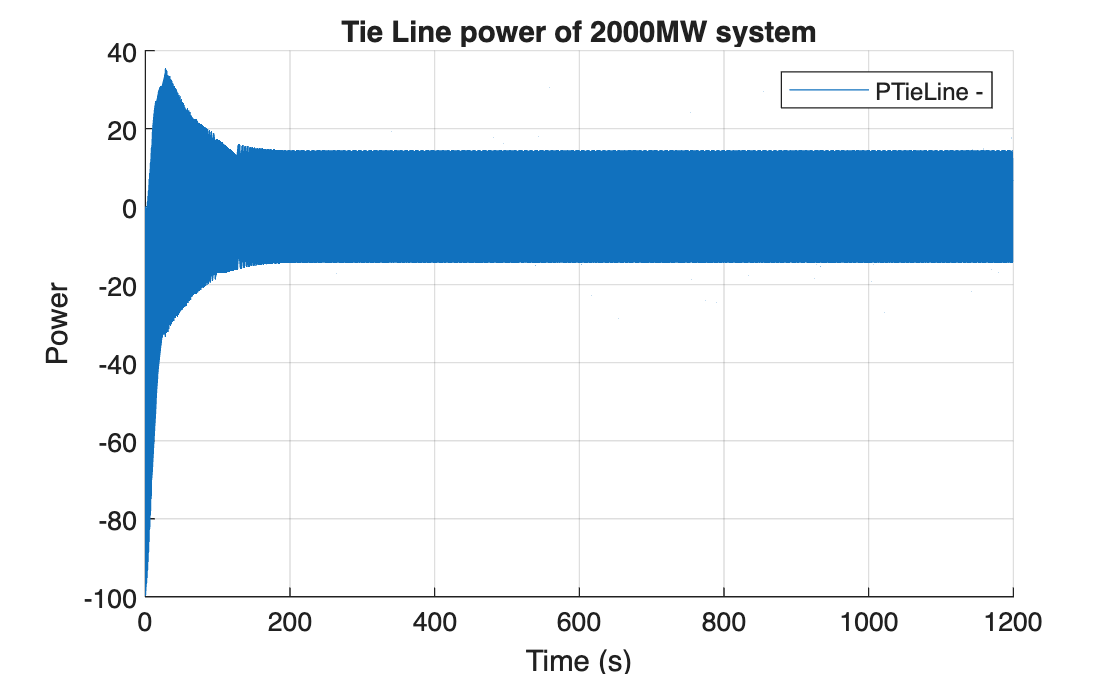



scopeNames = {'PTieLine'};

figure; hold on; grid on;

for i = 1:numel(scopeNames)
    name = scopeNames{i};

    % Try to get dataset directly from 'out'
    try
        ds = out.get(name);
    catch
        % Otherwise get it from logsout
        ds = out.logsout.get(name);
    end

    % Plot each signal in this scope
    for j = 1:ds.numElements
        sig = ds.get(j);
        plot(sig.Values.Time, sig.Values.Data, 'DisplayName', [name ' - ' sig.Name]);
    end
end


xlabel('Time (s)');
ylabel('Power');
title('Tie Line power of 2000MW system');
legend('show', 'Interpreter', 'none');


% Adding additional controls, we are able to get the freqency to 0 and have
% the tie line Power stabilize and oscillate around 0
% some problems we notice is how quick the responses are and the
% oscillations. 
% These can be mitigated by adding some delays and ramp controls, as well
% as fine tuning the control paramters of the model further. 


% R1 = 0.0060 * 2 * pi % rad / s MW 
% R2 = 0.0120 * 2 * pi % rad / s MW 
% 
% 
% M = 1.1141e+08 / 10^6 % convert to MW s^2 / rad
% D = 20 / ( 2 * pi) % MW s / rad
% 
% B = 1/R1 + 1/R2 + D
% 
% T = 20000
% K = 0.01